%% basic parameter
clear 
% data length, fs, f
L = 153600; fs = 614.4e6; 
% f = (1/4000)^(2n)
f = 34359740;
dt = 1/fs;
t = (1:L)'*dt;
tp = (1:10*L)'*(0.1*dt);

signal = 0;
simulate = 0;
store = 0;
align_method = 3;

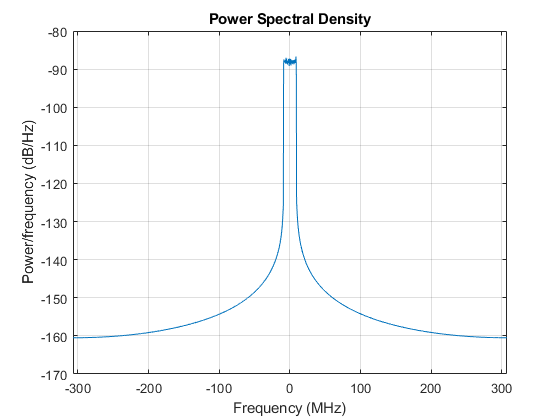

q = 0.5; i = 0.5;
if signal == 1
    %% singal tone
    x_raw = q*sin(2*pi*f*t)+i*cos(2*pi*f*t)*1j;    
elseif signal == 2
    %% double tone
    % x = (q*sin(2*pi*2*f*t)*1j + q*cos(2*pi*2*f*t)) + ((q*sin(2*pi*1*f*t)*1j + q*cos(2*pi*1*f*t)));
    x_raw = q*sin(2*pi*f*t)+i*cos(2*pi*f*t)*1j + q*cos(2*pi*f*t)+i*sin(2*pi*f*t)*1j;
elseif signal == 0
    load('18_Nov_2021_11_31_16_+0100_itersdata.mat');
    x_raw = 1.5*itersdata(4).uBB;
end

% plot the singal PSD
figure; pwelch(x_raw,2^12,[],[],614.4e6,'centered');

% figure; plot(real(x),imag(x),'.');

if simulate == 0
    % send it to SoC
    send_RFSoC([],x_raw,x_raw);
    % receive from SoC
    [yBB_raw,rxdata] = recv_RFSoC([]);    
elseif simulate == 1
    load asdasd.mat;
end

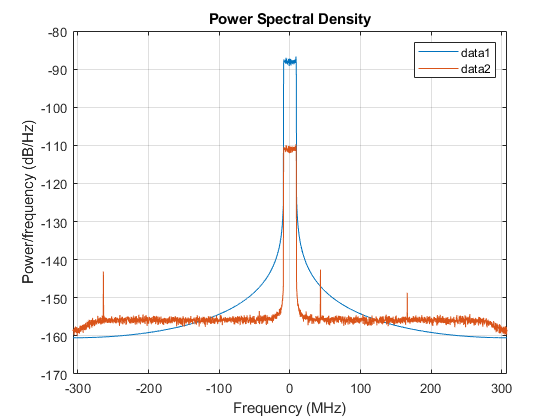

% plot the PSD
figure; pwelch([x_raw yBB_raw],2^12,[],[],614.4e6,'centered');
legend

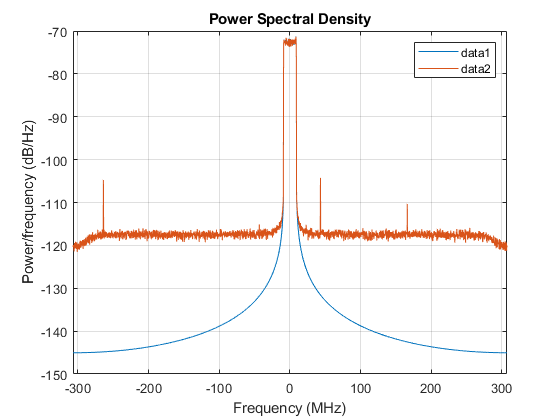

%rms
yBB = yBB_raw/(rms(yBB_raw));
x = x_raw/(rms(x_raw));
% yBB = yBB_raw;
% x = x_raw;
figure; pwelch([x yBB],2^12,[],[],614.4e6,'centered');
legend


% 

xp = interp1(t,x,tp,'spline');

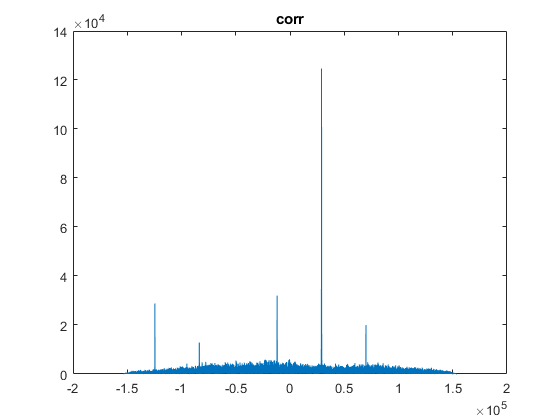

offset = 29056

index = 5

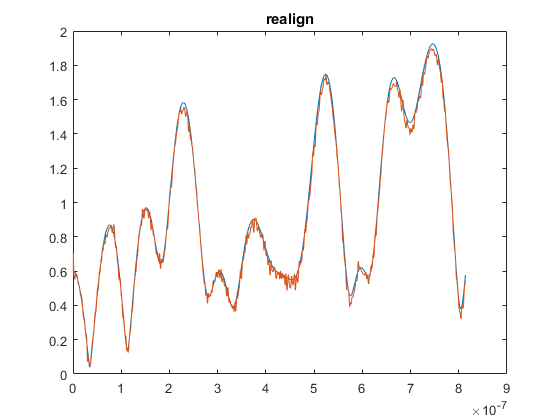

if align_method == 1
    % Interpolation  
    xp = interp1(t,x,tp,'spline');
    yBBp=interp1(t,yBB,tp,'spline');
    
    K = 10; N = 1; Npre = 1;
    x_up=zeros(length(x)*K,1);
    x_up(1:K:end)=x;
    % xp=x_up(1:Npre*N:end);
    
    t1 = 1; t2 = 150;
    t3 = 10*t1; t4 = 10*t2;
    
    figure; plot(tp(t3:t4),abs(xp(t3:t4)));
    hold on
    plot(t(t1:t2),abs(x(t1:t2)));
    % plot(t(t1:t2),abs(yBB(t1:t2)));
    
    figure; plot(tp(t3:t4),abs(yBBp(t3:t4)));
    hold on
    plot(t(t1:t2),abs(yBB(t1:t2)));
    % plot(tp(t3:t4),abs(xp(t3:t4)));
    
    % align
    t1 = 1; t2 = t1 + 5000;
    [r,lags] = xcorr(yBBp, xp);
    figure; plot(lags,abs(r));
    title("corr");
    [val,idx]=max(abs(r));
    offset=lags(idx)
    
    figure; plot((tp(t1:t2)),abs(xp(t1:t2)));
    % yBBp = circshift(yBBp, offset);
    hold on
    plot((tp(t1:t2)),abs(yBBp(t1:t2)));
    title("align");
    
    % realign
    error = 1e12;
    index = 0; temp = 0;
    for k=(-40:40)
        temp = sum((abs(circshift(yBBp, k))-abs(xp)).^2);
    %     disp(temp)
        if(temp < error)
            error = temp;
            index = k;
        end
    end
    
    offset1 = offset+index
    
    t1 = 1; t2 = t1+5000;
    t3 = t1; t4 = t2;
    
    figure; plot((tp(t1:t2)-tp(t1)),abs(xp(t1:t2)));
    yBBp1 = circshift(yBBp, -offset1);
    hold on
    plot((tp(t3:t4)-tp(t3)),abs(yBBp1(t3:t4)));
    title("realign");
    
    % yBB1 is the shifted signal
    % yBBp1 is the shifted signal
    
    yasd = downsample(yBBp1, 10, 9);
end

if align_method == 2
    t1 = 96100; t2 = t1 + 150;
    t3 = t1*10; t4 = 10*t2;
    
    % [r,lags] = xcorr(abs(yBB), abs(x));
    
    w = cconv(abs(x),abs(yBB(end:-1:1)));
    
    % w = cconv(real(x),real(yBB(end:-1:1)));
    
    % w = cconv(x,yBB(end:-1:1));
    
    [val,idx]=max(abs(w));
    idx = idx - L
    
    % error = 1e12;
    % index = 0;
    % temp = 0;
    % for k=(0:L)
    % %     temp = sum((abs(yBBp(t3+k:t4+k))-abs(xp(t1:t2))).^2);
    %     temp = sum((abs(circshift(yBB, k))-abs(x)).^2);
    % %     disp(temp)
    %     if(temp < error)
    %         error = temp;
    %         index_delete = k;
    %     end
    % end
    % disp(index_delete) 57520
    
    yBB_delete = circshift(yBB, idx);

    % realign    
    resolution = 40;
    
    xp1=dpd_resample(x,resolution,1,0.5,'ZEROS');
    yp1=dpd_resample(yBB_delete,resolution,1,0.5,'NORMAL');
    
    DLEAY = [-20:20];
    RESULTS=zeros(length(DLEAY),1);
    
    for niter=1:length(DLEAY)
        RESULTS(niter,1)=sum(abs(xp1).* circshift(abs(yp1),DLEAY(niter)));
    end
    
    [val,pos]=max(RESULTS(:,1));
    DLEAY(pos)
    yp1=circshift(yp1,DLEAY(pos));
    
    t1 = 1; t2 = t1+5000;
    t3 = t1; t4 = t2;
    figure; plot((tp(t1:t2)-tp(t1)),abs(xp(t1:t2)));

    hold on
    plot((tp(t3:t4)-tp(t3)),abs(yp1(t3:t4)));
    title("realign");    
    
    yasd=yp1(1:resolution:end);
      
end

if align_method == 3
    [r,lags] = xcorr(yBB, x);
    figure; plot(lags,abs(r));
    title("corr");
    [val,idx]=max(abs(r));
    offset=lags(idx)
    
    yBB1 = circshift(yBB, -offset);
    
    % Interpolation
    
    xp = interp1(t,x,tp,'spline');
    yBBp=interp1(t,yBB1,tp,'spline'); 
    
    % realign
    DLEAY = [-40:40];
    RESULTS=zeros(length(DLEAY),1);
    error = 1e12;
    for k= -20:20
        temp = sum((abs(circshift(yBBp, k))-abs(xp)).^2);
%         temp = sum(abs(xp).* abs(circshift(yBBp,k)));
%         disp(temp)
        if(temp < error)
            error = temp;
            index = k;
        end
    end
%     [val,pos]=max(RESULTS(:,1));
%     index = DLEAY(pos)
    index
    
    t1 = 1; t2 = t1+5000;
    figure; plot((tp(t1:t2)-tp(t1)),abs(xp(t1:t2)));
    yBBp1 = circshift(yBBp, index);
%     yBBp1 = yBBp;
    hold on
    plot((tp(t1:t2)-tp(t1)),abs(yBBp1(t1:t2)));
    title("realign");
    
    % yBBp1 is the shifted signal
    yasd = downsample(yBBp1, 10, 9);
    
end

%% phase
compensation = 0;
phase_resolution = 30;
range = pi;

for loop = 1:3
    rotation = range*[-phase_resolution:1:phase_resolution]/phase_resolution;
    % x_ref = x, x = ypp
    y_temp = yasd.*exp(1j*rotation);
    [val, pos] = min(abs(mean(y_temp - x)));
    
    temp_compensation = rotation(pos);
    compensation = compensation + temp_compensation;
    
    yasd = yasd.*exp(1j*compensation);
    range = range/phase_resolution;
end

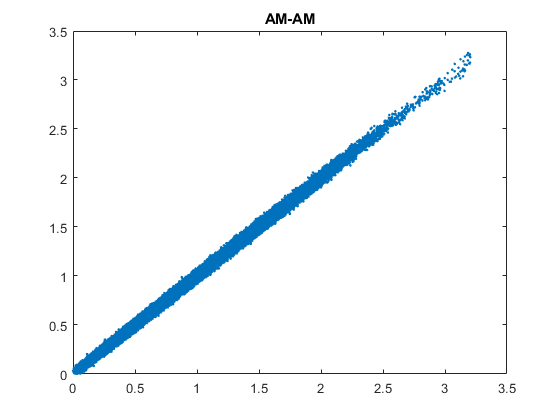

% AM-AM
figure; plot(abs(x), abs(yasd),'.')
title("AM-AM");

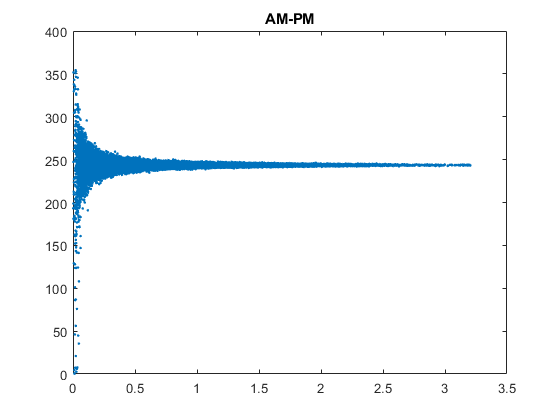


% AM-PM
w_ypp = angle(yasd)*180/pi;
w_x = angle(x)*180/pi;
% figure; plot(abs(x), abs(abs(w_x-w_ypp)-180),'.')
ang = w_x-w_ypp;
for i = 1:length(ang)
    if ang(i)<0
        ang(i) = ang(i)+360;
    end
end
figure; plot(abs(x), (ang),'.')
title("AM-PM");


if store == 1
    save("asdasd.mat", "yBB", "x", "t", "tp", "xp", "yBBp")
end

% NMSE

error = abs(x)-abs(yasd);
num = mean(abs(error).^2);
den = mean(abs(x).^2 );
NMSE = 10*log10(num/den);
NMSE

NMSE = -31.8424


% % both files should be uploaded manually
% % receive from python and compare
% rx_py = load('rx.mat');
% yBB_py = rx_py.yBB;
% figure;
% pwelch([yBB yBB_py],2^12,[],[],614.4e6,'centered');
% legend;
% % check tx.amt
% tx_py = load('tx.mat');
% xBB_py = tx_py.ch2;
% figure;
% pwelch(xBB_py,2^12,[],[],614.4e6,'centered');
% legend;

% save('tx_new.mat','tx_py');

function [y]=dpd_resample(x,Kx,Nx,BWr,type)

factors_Nx=factor(Nx);
K=Kx;
Npre=1;
N=Nx;

oversampling=floor(0.5/BWr);

switch type
   
    case 'NORMAL'
        
        for n=1:1:length(factors_Nx)
            buffer=factors_Nx(n);
            if ( (1/buffer)>2*BWr )
            Npre=factors_Nx(n);
            N=Nx/Npre;    
            end
        end
        
        for n=2:1:length(factors_Nx)
            buffer=factors_Nx(1)*factors_Nx(n);
            if ( ((1/buffer )>2*BWr) && (buffer>Npre) )
            Npre=buffer;
            N=Nx/Npre;    
            end
        end
                 
        if (Npre>1) 
           x=dpd_FFTFilter(1,0,BWr,x,'LP'); 
        end
        
%         Npre
        
        x_predown=x(1:Npre:end);   
        BWr2=BWr*Npre;
%         BWr2/K
%         K
        x_up=zeros(length(x_predown)*K,1);
        x_up(1:K:end)=x_predown;        
        x_up=dpd_FFTFilter(1,0,(BWr2/K),x_up,'LP');   
        x_up=x_up*K;
        
        y=x_up(1:N:end);
      
    case 'ZEROS'      
        x_up=zeros(length(x)*K,1);
        x_up(1:K:end)=x;
        y=x_up(1:Npre*N:end);
        
    otherwise
end

end

function [y]=dpd_FFTFilter(Fs,Fo,BWa,x,type)
    L=length(x);
    BW=ceil(L*BWa/Fs);
    plantilla_fft=zeros(L,1);    
    plantilla_fft(1:1:BW,1)=ones(BW,1);
    plantilla_fft(L-BW+2:1:L,1)=ones(BW-1,1);
    
    tf=fft(x); 
    y=ifft(plantilla_fft.*tf);
end
